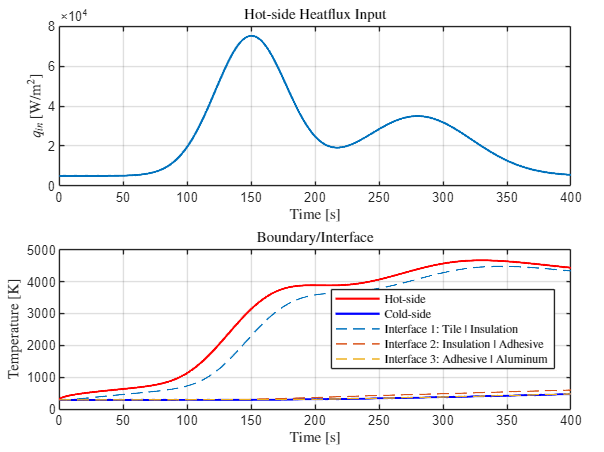

%==========================================================================
% transientConduction_multilayer: Run multilayer TPS solver and plot key outputs
%
% Purpose:
%   Execute multilayerTPS(TPS) using a default demo configuration,
%   then visualize hot/cold and interface temperatures over time, final
%   temperature profile across thickness, and (if available) the full
%   space–time temperature map. Also plots hot-side heat flux if BC=flux.
%==========================================================================

clear; clc; close all;

%% ------------------------- Build configuration --------------------------
TPS = betaTPS;   % Provided by the solver file

%% ----------------------------- Run solver -------------------------------
out = multilayerTPS(TPS);

% Convenience aliases
t   = out.t;
x   = out.x;
Th  = out.T_hot;
Tc  = out.T_cold;
Tif = out.T_ifaces;
Tf  = out.T_end;
hasHist = ~isempty(out.T);

% Layer interface locations for plotting (if any)
iface_idx = [];
iface_x   = [];
layer_names = arrayfun(@(L) string(L.name), out.meta.layers, 'UniformOutput', true);
if isfield(out.meta, 'idx_layer_end')
    iface_idx = out.meta.idx_layer_end(1:end-1);
    if ~isempty(iface_idx)
        iface_x = x(iface_idx);
    end
end

%% -------------------------- Plot: q(t) & T(t) ---------------------------
% If hot BC is a flux, plot the input heat flux vs time alongside T_hot/T_cold
if isfield(TPS,'hotBC') && isfield(TPS.hotBC,'type') && strcmpi(TPS.hotBC.type,'flux')
    qfun = TPS.hotBC.qfun;
    q_t  = arrayfun(qfun, t);

    figure('Name','Hot flux and boundary temperatures','Color','w');
    tiledlayout(2,1,'Padding','compact','TileSpacing','compact');

    % (a) Heat flux at hot side
    ax1 = nexttile;
    plot(t, q_t, 'LineWidth', 1.5);
    grid on; 
    xlabel('Time [s]', 'Interpreter', 'latex'); 
    ylabel('$q_{in}$ [W/m$^2$]', 'Interpreter', 'latex'); 
    title('Hot-side Heatflux Input', 'Interpreter', 'latex'); 

    % (b) Hot / Cold temperatures
    ax2 = nexttile; 
    plot(t, Th, 'r', 'LineWidth', 1.5); hold on;
    plot(t, Tc, 'b', 'LineWidth', 1.5);
    grid on; 
    xlabel('Time [s]', 'Interpreter', 'latex'); 
    ylabel('Temperature [K]', 'Interpreter', 'latex'); 
    leg = {'Hot-side','Cold-side'};

    % Add interface temperatures if present
    if ~isempty(Tif)
        cmap = lines(size(Tif,2));
        for k = 1:size(Tif,2)
            plot(t, Tif(:,k), '--', 'Color', cmap(k,:), 'LineWidth', 1.0);
            if numel(layer_names) >= k+1
                leg{end+1} = sprintf('Interface %d: %s | %s', k, layer_names(k), layer_names(k+1));
            else
                leg{end+1} = sprintf('Interface %d', k);
            end
        end
    end
    legend(leg, 'Location','best', 'Interpreter', 'latex'); 
    title('Boundary/Interface', 'Interpreter', 'latex'); 

else
    % No flux BC: just plot temperatures at hot/cold and interfaces
    figure('Name','Boundary and interface temperatures','Color','w');
    plot(t, Th, 'r', 'LineWidth', 1.5); hold on;
    plot(t, Tc, 'b', 'LineWidth', 1.5);
    grid on; 
    xlabel('Time [s]', 'Interpreter', 'latex'); 
    ylabel('Temperature [K]', 'Interpreter', 'latex'); 
    leg = {'Hot-side','Cold-side'};
    if ~isempty(Tif)
        cmap = lines(size(Tif,2));
        for k = 1:size(Tif,2)
            plot(t, Tif(:,k), '--', 'Color', cmap(k,:), 'LineWidth', 1.0);
            if numel(layer_names) >= k+1
                leg{end+1} = sprintf('Interface %d: %s | %s', k, layer_names(k), layer_names(k+1));
            else
                leg{end+1} = sprintf('Interface %d', k);
            end
        end
    end
    legend(leg, 'Location','best', 'Interpreter', 'latex'); 
    title('Boundary/Interface', 'Interpreter', 'latex'); 
end

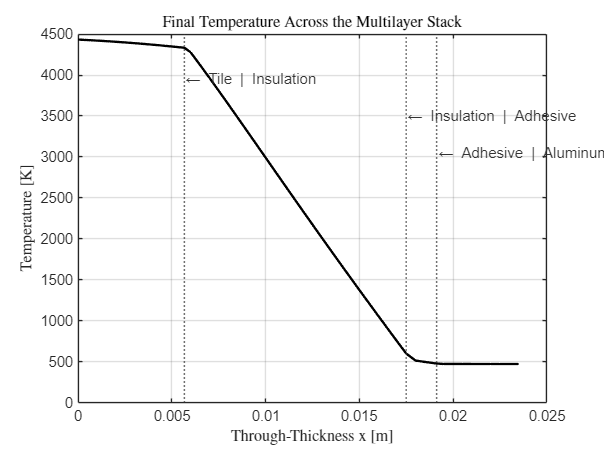


%% ----------------------- Plot: final profile T(x) -----------------------
figure('Name','Final temperature profile','Color','w');
plot(x, Tf, 'k', 'LineWidth', 1.6); hold on; grid on;
xlabel('Through-Thickness x [m]', 'Interpreter', 'latex');  
ylabel('Temperature [K]', 'Interpreter', 'latex'); 
title('Final Temperature Across the Multilayer Stack', 'Interpreter', 'latex'); 

% Draw layer interface markers and staggered labels from top down
if ~isempty(iface_x)
    yl = ylim;
    dy = 0.1 * (yl(2) - yl(1));  % Vertical spacing between labels
    for j = 1:numel(iface_x)
        % Draw vertical dashed line at interface
        xline(iface_x(j), ':', 'Color', [0.2 0.2 0.2], 'LineWidth', 1.0);
        % Staggered Y position: start near top and go down
        yPos = yl(2) - dy - (j-1)*dy;
        % Ensure it doesn't go below the bottom
        if yPos < yl(1) + dy
            yPos = yl(1) + dy;
        end
        % Place label
        text(iface_x(j), yPos, ...
             sprintf('\\leftarrow %s | %s', layer_names(j), layer_names(j+1)), ...
             'Color', [0.2 0.2 0.2], ...
             'HorizontalAlignment','left', ...
             'VerticalAlignment','top', ...
             'Rotation', 0);
    end
end

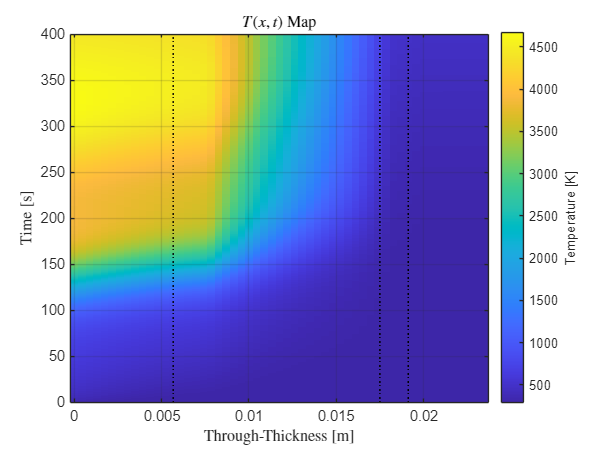


%% ------------- Plot: space–time temperature map T(x,t) ------------------
if hasHist
    figure('Name','Space–time temperature map','Color','w');
    imagesc(x, t, out.T); axis xy; grid on;
    xlabel('Through-Thickness [m]', 'Interpreter', 'latex');  
    ylabel('Time [s]', 'Interpreter', 'latex');  
    cb = colorbar; cb.Label.String = 'Temperature [K]';
    title('$T(x, t)$ Map', 'Interpreter', 'latex');  

    % Overlay layer interfaces
    hold on;
    if ~isempty(iface_x)
        for j = 1:numel(iface_x)
            plot([iface_x(j) iface_x(j)], [t(1) t(end)], 'k:', 'LineWidth', 1.0);
        end
    end
end


%% ---------------------------- Energy report -----------------------------
if isfield(out,'energy') && ~isempty(fieldnames(out.energy))
    Ein   = out.energy.Ein;
    Eout  = out.energy.Eout_cold;
    U     = out.energy.U;
    resid = out.energy.residual;

    fprintf('\n=== Energy summary ===\n');
    fprintf('  Ein (hot side, flux)      : %.3f kJ\n',  Ein/1e3);
    fprintf('  Eout (cold side, Robin)   : %.3f kJ\n',  Eout/1e3);
    fprintf('  U (internal, final state) : %.3f kJ\n',  U/1e3);
    fprintf('  Residual (Ein - Eout - U) : %.3f kJ\n',  resid/1e3);
    fprintf('=======================\n\n');
end


=== Energy summary ===


  Ein (hot side, flux)      : 498.032 kJ


  Eout (cold side, Robin)   : 0.000 kJ


  U (internal, final state) : 16837.187 kJ


  Residual (Ein - Eout - U) : -16339.155 kJ
